# Plot Selkov against ES data

clear all

load('..\Data\ES_down.mat')
ES_traj_down = [good_na_aug, good_nb_aug];
ES_eta_down = [good_eta_a_aug, good_eta_b_aug];
ES_PS_down = [ES_traj_down ES_eta_down];

load('..\Data\ES_up.mat')
ES_traj = [upp_good_na upp_good_nb];
ES_eta = [upp_good_eta_a,upp_good_eta_b];
ES_PS_up = [ES_traj ES_eta];

load( "..\Data\Selkov_descend_1_1straight_4000_14-Jul-2022.mat")

PS_traj_up = PS_traj;

load( "..\Data\Selkov_descend_1_2spiral_2500_09-Aug-2022.mat")
PS_traj_down = PS_traj;

load("..\Data\Selkov_descend_1_2spiral_4000_11-Aug-2022.mat")
PS_traj_down = PS_traj;

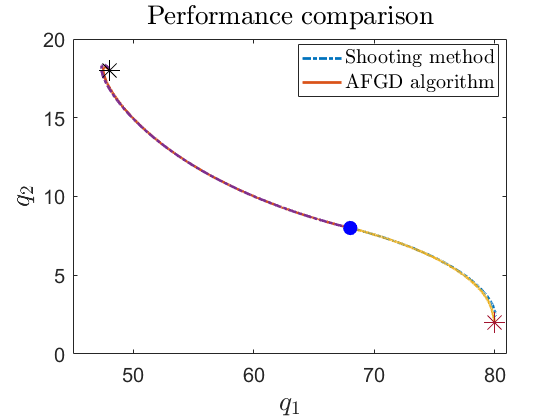

figure()
plot(ES_traj_down(:,1),ES_traj_down(:,2),'-.','LineWidth',2)
hold on
plot(PS_traj_up(:,1),PS_traj_up(:,2),'LineWidth',2)
plot(PS_traj_down(:,1),PS_traj_down(:,2),'LineWidth',2)
plot(ES_traj(:,1),ES_traj(:,2),'-.','LineWidth',2)
plot(PS_traj_up(1,1),PS_traj_up(1,2),'k*','MarkerSize',15)
plot(PS_traj_up(end,1),PS_traj_up(end,2),'bo','MarkerSize',10,'MarkerFaceColor','b')
plot(PS_traj_down(1,1),PS_traj_down(1,2),'*','MarkerSize',15)
hold off
h1 = legend('Shooting method','AFGD algorithm','location','best');
set(h1,'Interpreter','latex');
h1.FontSize = 15;
ax=gca;
ax.FontSize = 15;
xlim([45 81])
xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title('Performance comparison','interpreter','latex','FontSize',20)

[S_traj_up,len_curve_up] = func_S_len(PS_traj_up);
[S_traj_down,len_curve_down] = func_S_len(PS_traj_down);
[S_traj_ES_up,len_curve_ES_up] = func_S_len(ES_PS_up);
len_curve_ES_up = len_curve_ES_up - len_curve_ES_up(end);
[S_traj_ES_down,len_curve_ES_down] = func_S_len(ES_PS_down);
len_curve_ES_down = len_curve_ES_down(end) - len_curve_ES_down ;


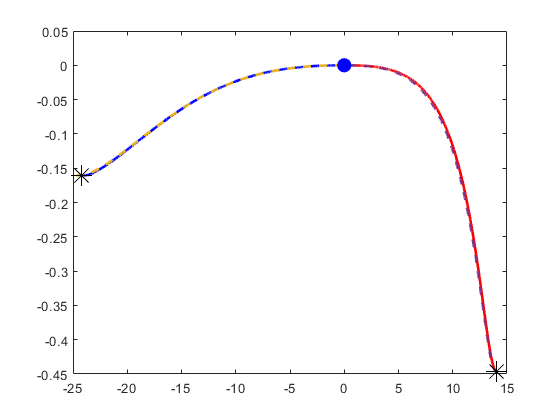

figure()
plot(-len_curve_up,flip(S_traj_up),'b','LineWidth',2)
hold on
plot(flip(len_curve_down),S_traj_down,'r','LineWidth',2)
plot(len_curve_ES_up,S_traj_ES_up,'--','LineWidth',2)
plot(len_curve_ES_down,S_traj_ES_down,'--','LineWidth',2)
plot(0,0,'bo','MarkerSize',10,'MarkerFaceColor','b')
plot(-len_curve_up(end),S_traj_up(1),'k*','MarkerSize',15)
plot(len_curve_down(end),S_traj_down(1),'k*','MarkerSize',15)
hold off

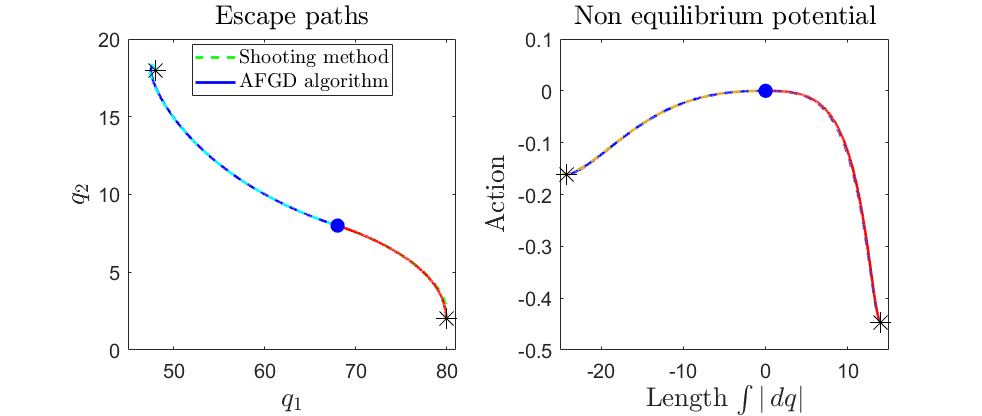

figure()
subplot(1,2,1)
plot(ES_traj_down(:,1),ES_traj_down(:,2),'g--','LineWidth',2)
hold on
plot(PS_traj_up(:,1),PS_traj_up(:,2),'b','LineWidth',2)
plot(PS_traj_down(:,1),PS_traj_down(:,2),'r','LineWidth',2)
plot(ES_traj(:,1),ES_traj(:,2),'c--','LineWidth',2)
plot(PS_traj_up(1,1),PS_traj_up(1,2),'k*','MarkerSize',15)
plot(PS_traj_up(end,1),PS_traj_up(end,2),'bo','MarkerSize',10,'MarkerFaceColor','b')
plot(PS_traj_down(1,1),PS_traj_down(1,2),'k*','MarkerSize',15)
hold off
h1 = legend('Shooting method','AFGD algorithm','location','best');
set(h1,'Interpreter','latex');
h1.FontSize = 15;
ax=gca;
ax.FontSize = 15;
xlim([45 81])
xlabel('$q_1$','interpreter','latex','FontSize',20)
ylabel('$q_2$','interpreter','latex','FontSize',20)
title('Escape paths','interpreter','latex','FontSize',20)

subplot(1,2,2)

plot(-len_curve_up,flip(S_traj_up),'b','LineWidth',2)
hold on
plot(flip(len_curve_down),S_traj_down,'r','LineWidth',2)
plot(len_curve_ES_up,S_traj_ES_up,'--','LineWidth',2)
plot(len_curve_ES_down,S_traj_ES_down,'--','LineWidth',2)
plot(0,0,'bo','MarkerSize',10,'MarkerFaceColor','b')
plot(-len_curve_up(end),S_traj_up(1),'k*','MarkerSize',15)
plot(len_curve_down(end),S_traj_down(1),'k*','MarkerSize',15)
hold off
ax=gca;
ax.FontSize = 15;
xlabel('Length $\int|\,dq|$','interpreter','latex','FontSize',20)
ylabel('Action','interpreter','latex','FontSize',20)
title('Non equilibrium potential','interpreter','latex','FontSize',20)
xlim([-25 15])
x0=0.1;
y0=0.1;
width=26;
height=11;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])
save_plot_name = 'Plots\Selkov_hc_escape.png';
saveas(gcf,save_plot_name)

function [S_traj,len_curve] = func_S_len(PS_traj)
    num_spec = size(PS_traj,2)/2;
    [action_S_new, S_traj] = action_PS_traj(PS_traj);
    S_traj = S_traj - S_traj(end);
    traj_ic = PS_traj(:,1:num_spec);
    diff_traj = diff(traj_ic);    
    dlen_traj =(sum(diff_traj.*diff_traj,2)).^(0.5);
    dlen_traj = [0; dlen_traj];
    len_curve = cumsum(dlen_traj);
end